**Sprawozdanie 2**

**Jakub Szczypek **

**gr.5a air WEAIiIB**

Ćwiczenie1 

Część I–MATLAB jako środowisko programistyczne:

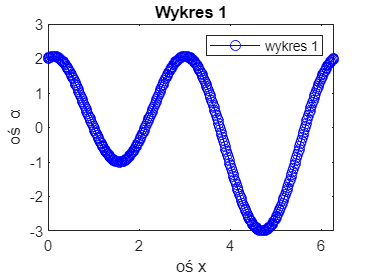

%plot(x);
%plot(x,y);
%plot(x,y,'r');


clear all
x=0:pi/180:2*pi;
y=sin(x)+2*cos(2*x);
plot(x,y,'-bo')
title('Wykres 1')
legend('wykres 1')
ylabel('oś \alpha')
xlabel('oś x')

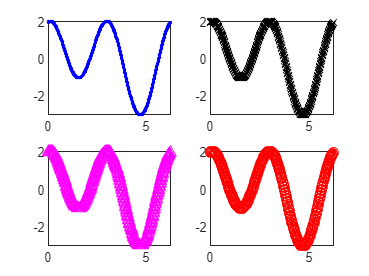



x=0:pi/180:2*pi;
y=sin(x)+2*cos(2*x);
subplot(2,2,1)
plot(x,y,'-b.')
subplot(2,2,4)
plot(x,y,'-ro')
subplot(2,2,2)
plot(x,y,'-kx')
subplot(2,2,3)
plot(x,y,'-m^')

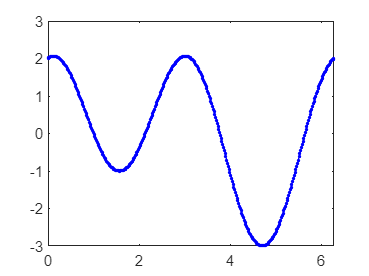



figure
x=0:pi/180:2*pi;
y1=sin(x)+2*cos(2*x);
y2=sin(2*x)-2*cos(x);
plot(x,y1,'-b.')

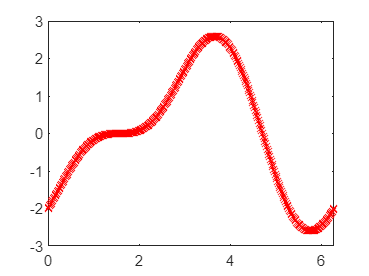

plot(x,y2,'-rx')

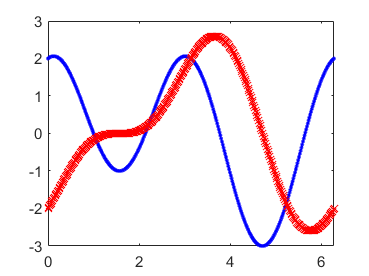



figure
plot(x,y1,'-b.')
hold on
plot(x,y2,'-rx')
hold off


%clear all
%x=0:pi/180:2*pi;
%y=sin(x)+2*cos(2*x);
%save mojedane x y      - Użylem komentarza by moc dalej kontuowac
                          %obliczenia
%clear all
%plot(x,y)
%load mojedane
%plot(x,y)
%saveas(gcf,'przyklad.tiff','tiffn')

clear all
W([1 2 3])=[2 4 6]

W =      2     4     6


W = 'abc'             

W = 'abc'

W([1 2 3])=[72 74 76]

W = 'HJL'

class(W)

ans = 'char'

 
%clear all
%[x1,y1]=funkcja1(4,3,1);
%subplot(2,1,1);plot(x1,y1)
                               %- Użylem komentarza by moc dalej kontuowac
                                  %obliczenia
%[x2,y2]=funkcja1(2,2,-1);
%subplot(2,1,2);plot(x2,y2)
 
%load mojedane
%createfigure(x, y)

Ćwiczenie 2

Część II –MATLAB typy danych

%C = {2 rand(3); pi 'abc'}
%C{1,2}


%mojastrutktura.polel1 = 'a'
%mojastrutktura =
%    struct with fields:
%        pole1: 'a'
%mojastrutktura.polel2 = 123        -Użylem komentarza by moc dalej
%                                    kontynuowac ocliczenia
%mojastrutktura =
%    struct with fields:
%        pole1: 'a'
%        pole2: 123
   

%f1 = @(x) x.^2 – 2*x
%f1 =
%    function_handle with value:
%        @(x)x.^2-2*x
%f1([3,4,5])


Imie = {'Rafał';'Monika';'Paweł';'Elżbieta';'Mirek'};
Wiek = [38;43;38;40;49];
Wzrost = [71;69;64;67;64];
Waga = [176;163;131;133;119];
T = table(Wiek,Wzrost,Waga,'RowNames',Imie)

T = 5×3 table
                Wiek    Wzrost    Waga
                ____    ______    ____

    Rafał        38       71      176 
    Monika       43       69      163 
    Paweł        38       64      131 
    Elżbieta     40       67      133 
    Mirek        49       64      119 


clear all

Ćwiczenie 3

Część III–MATLAB jako środowisko programistyczne

Zad a

DaneP = importfile('daneP.csv', [4, 298])

DaneP = 295×3 table
      R         G         B   
    ______    ______    ______

    218.42    183.59    174.75
    220.81    186.66    171.47
    248.49    231.02    226.64
    248.13    230.92    227.38
    247.13    229.84    225.75
    216.76    179.22    174.79
    214.79    178.86    174.59
     214.4    177.96    173.68
    212.29    174.93    171.19
    212.38    174.78    170.52
    212.26    174.97    170.99
    207.07    175.98    164.77
    207.15    176.11    164.93
    206.89    176.19    164.92
    206.96    176.31    165.02
    206.87    176.48    164.95


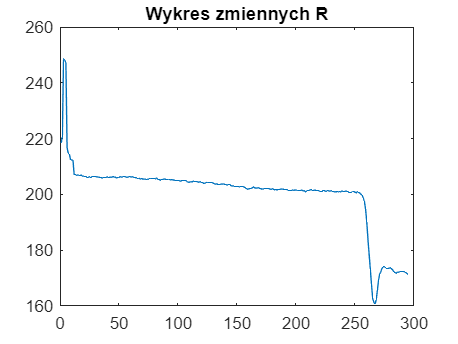

R = DaneP{:, 1};
plot(R)
title('Wykres zmiennych R')

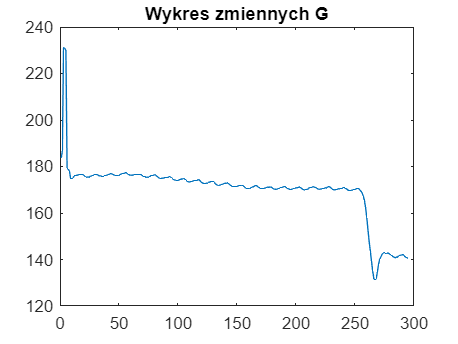

G = DaneP{:, 2};
plot(G)
title('Wykres zmiennych G')

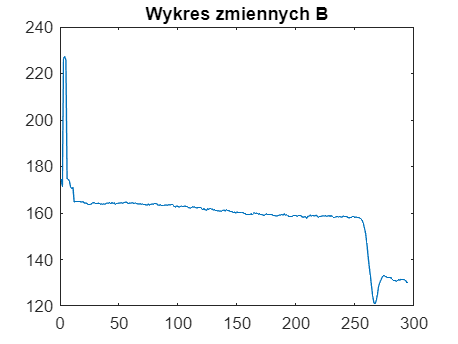

B = DaneP{:, 3};
plot(B)
title('Wykres zmiennych B')

Zad b

W tym podpunkcie wybieram drugą kolumnę z danych (kolumnę G), ponieważ na niej najlpepiej widać okresowość

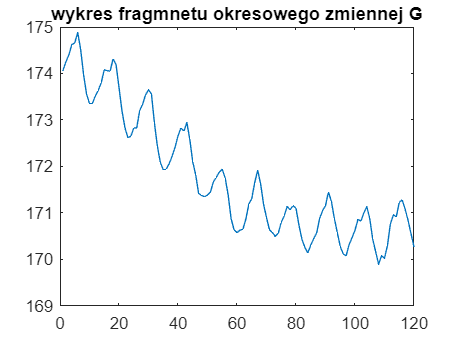

figure
G2 = DaneP{100:220,2};   %Wybranie według mnie części funkcji gdzie dobrze widac okresowość
plot(G2)
xlim([0 120])
title("wykres fragmnetu okresowego zmiennej G")

Zad c

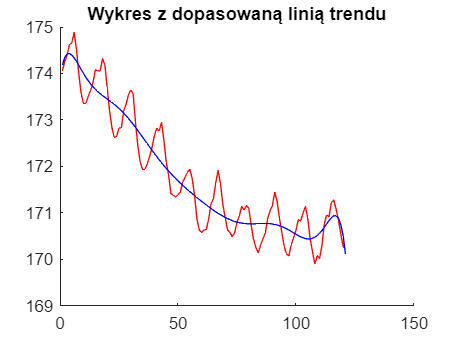

x = length(G2);
x = linspace(1,x,x);

% dopasowanie najlepszego wielomianu
n = [];
i=1;
while i<11
    [p,S,mu] = polyfit(x,G2,i);  % funkcja zwraca wektor współczynników
    y = polyval(p,x,[],mu);  
    y = y(:);
    % p -wektor współczynników wielomianu, 
    % x = punkty, dla których zwracane są odpwowiednie wartości wielomianu
    % mu = wektor dwuelementowy zwracający wartości centrowania i
    % skalowania,  S - struktura szacowania błędów
    n(i)=norm(G2-y);
    i = i+1;
end
figure
[p,S,mu] = polyfit(x,G2,i);
hold on
plot(x,G2,"r")
plot(x,y,"b")
title("Wykres z dopasowaną linią trendu")
hold off


bez_trendu = G2-y

bez_trendu =    -0.1250
   -0.0953
   -0.0191
    0.1897
    0.2621
    0.5431
    0.2611
   -0.2023
   -0.5237
   -0.6472


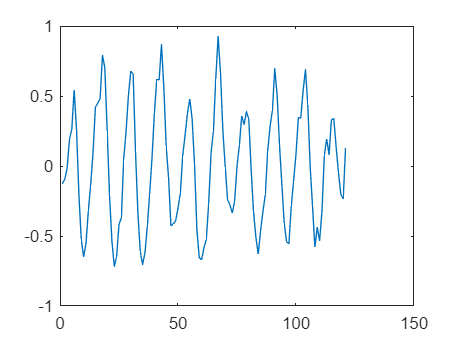

plot(bez_trendu)

Zad d

Fs = 60*15;                    %Częstotliwość próbkowania
T = 1/Fs;                      %Okres pobierania próbek
L = length(bez_trendu);        %Długość sygnału
t = (0:L-1)*T;

Y = fft(bez_trendu);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

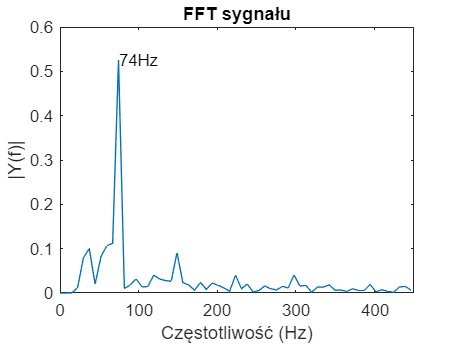

P1(2:end-1)=2*P1(2:end-1);
f = Fs*(0:(L/2))/L; 
plot(f, P1)
xlim([0,295]);
[w,i] = max(P1);
text(f(i),P1(i),string(round(f(i)))+"Hz")
title("FFT sygnału")
xlabel('Częstotliwość (Hz)')
ylabel('|Y(f)|')
axis([0 450 0 0.6])

Ćwiczenie 4

Część IV – MATLAB typy danych

Zad a

R = randn(3,3)

R =    -1.6642    0.4227   -1.2128
   -0.5900   -1.6702    0.0662
   -0.2781    0.4716    0.6524


A = uint32(100);
C = double(1.73)

C = 1.7300

B = uint32(R*double(A))

B = 3×3 uint32 matrix
    0   42    0
    0    0    7
    0   47   65


whos("A")

  Name      Size            Bytes  Class     Attributes

  A         1x1                 4  uint32              



whos("C")

  Name      Size            Bytes  Class     Attributes

  C         1x1                 8  double              



%Po wykonaniu działania każda wartość ujemna została zastąpiana zerem.
%Części ułamkowe liczb zostały usunięte.

Zad b

str1 = 'ćwiczenie 2';
str2 = 'labpratorium 1';
str3 = strvcat(str1, str2)

str3 = 2×14 char array
    'ćwiczenie 2   '
    'labpratorium 1'


Zad c

str1 = 'Krasnoludy przeszły przez rzekę w bród, nie zamoczywszy swych bród i do tego zmywszy ze swych nóg brud'

str1 = 'Krasnoludy przeszły przez rzekę w bród, nie zamoczywszy swych bród i do tego zmywszy ze swych nóg brud'

indexes = regexp(str1,'b[^u ]*d')

indexes =     35    63


Zad d

tab = {123,'abcd'; rand(3,3), 0.1}

tab = 2×2 cell array
    {[     123]}    {'abcd'  }
    {3×3 double}    {[0.1000]}


tab{2,1}=tab{2,1} + 100;
tab{2,1}

ans =   100.7150  100.3342  100.0305
  100.9037  100.6987  100.7441
  100.8909  100.1978  100.5000


Zad e

func = @(x) x.^2 - 2*x + 4

func = function_handle with value:
    @(x)x.^2-2*x+4


q = integral(func,-2,2)

q = 21.3333

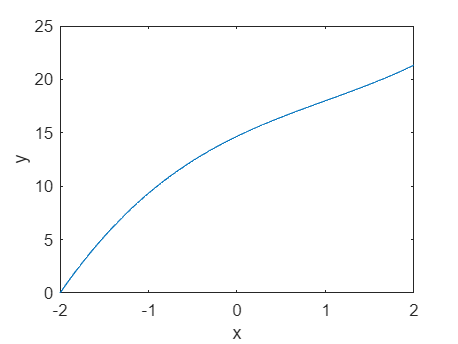


y = zeros(401,1);
x = -2:0.01:2;
for i = 1:1:401
    y(i)= integral(func,-2,x(i));
end
y;
figure
plot(x,y)
xlabel("x")
ylabel("y")

Zad f

Imie={'Rafał';'Monika';'Paweł';'Elżbieta';'Marek'};
Matematyka = randi(100, 5, 1);
Fizyka = randi(100, 5, 1);
Chemia = randi(100, 5, 1);
T =table(Matematyka, Fizyka, Chemia, 'RowNames', Imie)

T = 5×3 table
                Matematyka    Fizyka    Chemia
                __________    ______    ______

    Rafał           48          81         3  
    Monika          91          58        49  
    Paweł           61          19        17  
    Elżbieta        62          24        98  
    Marek           86          89        72  


writetable(T,'Tabela.csv')